Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.
Számolás: Pálya generálás...


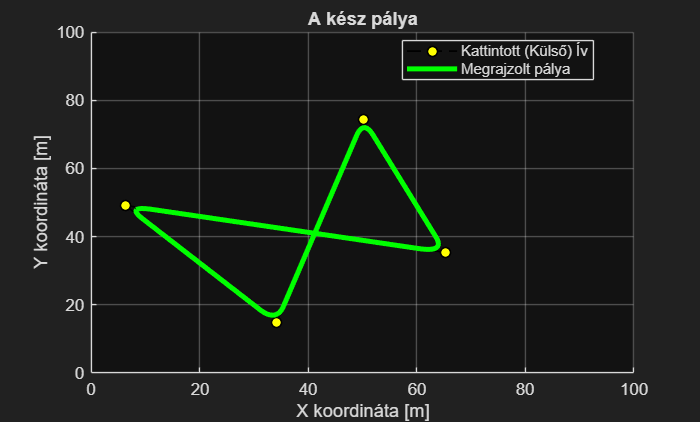

%% ============================================================
%  MAIN SCRIPT
%  ------------------------------------------------------------
%  Project name   : Tube MPC optimization with neural network
%  Author         : Bene Ádám
%  Date           : 2026.04.28.
%  Description    : Main execution script that calls the
%                   required submodules and processing steps.
%
%  Note           : Run this file directly.
%% ============================================================

% reference path define for the controller
run("path_define.mlx")

--- CASADI TUBE MPC SZIMULÁCIÓ INDÍTÁSA ---
CasADi szimuláció fut... (az IPOPT megoldó dolgozik)
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  21.00us (  2.33us)         9
       nlp_g  |        0 (       0)  49.00us (  5.44us)         9
  nlp_grad_f  |        0 (       0)  24.00us (  2.40us)        10
  nlp_hess_l  |        0 (       0)  34.00us (  4.25us)         8
   nlp_jac_g  |        0 (       0)  26.00us (  2.60us)        10
       total  | 754.00ms (754.00ms) 753.32ms (753.32ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  26.00us (  3.25us)         8
       nlp_g  |        0 (       0)  46.00us (  5.75us)         8
  nlp_grad_f  |        0 (       0)  32.00us (  3.56us)         9
  nlp_hess_l  |        0 (       0)  14.00us (  2.00us)         7
   nlp_jac_g  |        0 (       0)  29.00us (  3.22us)         9
       total  |  18.00ms ( 18.00ms)  17.69ms 

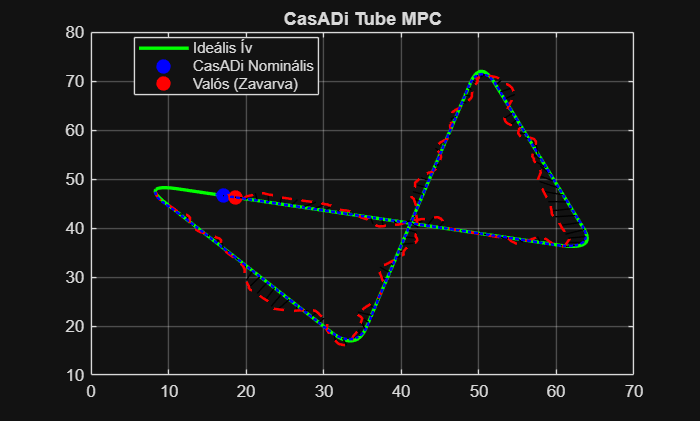


% run tube MPC for previously defined reference path
run("tube_mpc.mlx")

=== Neurális Háló Tanítása Indul ===


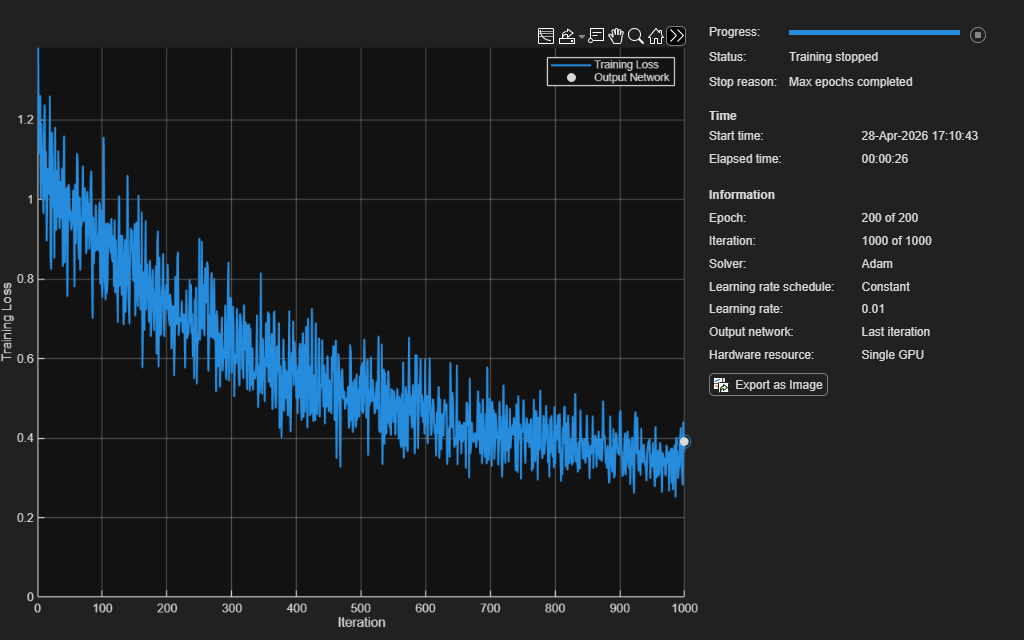

=== TANÍTÁS BEFEJEZŐDÖTT! A "net" nevű objektum elkészült. ===
--- Tesztelés az első időlépésen ---
Valós maradék hiba (a szimulációdból):
         0         0    0.9119    1.0890

Neurális háló által becsült hiba:
    0.0450    0.0036    1.1045    0.9820




% train the NN from the offline data of the previous simulation
run("train_nn.mlx")